# MAT 343 LAB 4 - Mohammad Almohammad

***NOTE:****  For each of the following problems you must create a script M-file rseparately and invoke it here in your livescript file. Make sure the function file is in the same folder as this livescript. Delete these notes upon submission.*

## Question 1

type lab4_exercise1.m    %print the M-file for question 1


clf
S = [0, 1, 1, 0, 0; 
     0, 0, 1, 1, 0];

plot(S(1,:), S(2,:), 'LineWidth', 2);
hold on;

% Shear matrix
T = [1, 0; 
     4, 1]; % Shears 4 units vertically

TS = T * S;

plot(TS(1,:), TS(2,:), '-r', 'LineWidth', 2);

title('Vertical Shear of 4 Units');
legend('Original Square', 'Sheared Square', 'Location', 'southeast');
axis([-1, 6, -1, 6]);
grid on;
axis equal;
hold off;


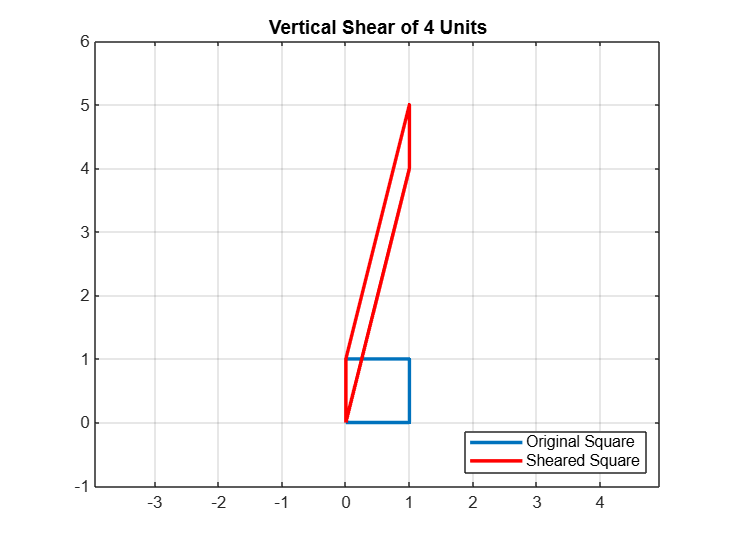

lab4_exercise1     % run the M-file for question 1

## Question 2

type lab4_exercise2.m    %print the M-file for question 2


clf
S = [0, 1, 1, 0, 0; 
     0, 0, 1, 1, 0];

plot(S(1,:), S(2,:), 'LineWidth', 2);
hold on;

theta = pi/6;
Q = [cos(theta), -sin(theta); 
     sin(theta),  cos(theta)];
T = [1, 1; 
     0, 1];

% Apply shear first, then rotation: Q*T*S
TQS = Q * T * S;

plot(TQS(1,:), TQS(2,:), '-r', 'LineWidth', 2);
title('Shear First, Then Rotate 30°');
legend('Original Square', 'Transformed Square', 'Location', 'southeast');
axis equal;
axis([-1, 3, -1, 3]);
grid on;
hold off;


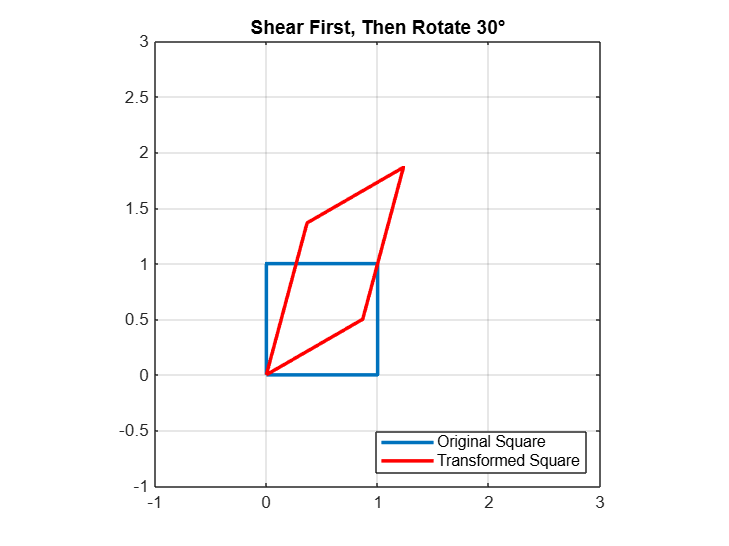

lab4_exercise2     % run the M-file for question 2

Is the result the same as Example? Does the order of the transformations matter?

Answer: No, result differs from Example 5 where rotation was applied first.

Yes. Matrix multiplication is not commutative as T*Q != Q*T so the order of transformations affects the final result.

## Question 3

*For this exercise you are not supposed to include the picture, so you do not need to run the M-file*

type lab4_exercise3.m    %print the M-file for question 3


clf
S = [0, 1, 1, 0, 0; 
     0, 0, 1, 1, 0];
p = plot(S(1,:), S(2,:));
axis([-2, 2, -2, 2]);
axis square;
grid on;
hold on;

theta = pi/8;

% CCW rotation in 16 steps
for i = 1:16
    Q = [cos(theta), -sin(theta); 
         sin(theta),  cos(theta)];
    S = Q * S;
    set(p, 'XData', S(1,:), 'YData', S(2,:));
    pause(0.3);
end

% CW in 16 steps
for i = 1:16
    Q = [cos(theta),  sin(theta); 
        -sin(theta),  cos(theta)];
    S = Q * S;
    set(p, 'XData', S(1,:), 'YData', S(2,:));
    pause(0.3);
end

hold off;


## Question 4

*For this exercise you are not supposed to include the picture, so you do not need to run the M-file*

type lab4_exercise4.m    %print the M-file for question 4


clf
S = [0, 1, 1, 0, 0; 
     0, 0, 1, 1, 0];
p = plot(S(1,:), S(2,:));
axis([-8, 8, -8, 8]);
axis square;
grid on;
hold on;

theta = pi/8;

% CCW + dilation
for i = 1:16
    Q = [cos(theta), -sin(theta); 
         sin(theta),  cos(theta)];
    D = (9/8) * eye(2); % Dilation
    T = D * Q;
    S = T * S;
    set(p, 'XData', S(1,:), 'YData', S(2,:));
    pause(0.25);
end

% CW + contraction
for i = 1:16
    Q = [cos(theta),  sin(theta); 
        -sin(theta),  cos(theta)];
    D = (8/9) * eye(2); 
    T = D * Q;
    S = T * S;
    set(p, 'XData', S(1,:), 'YData', S(2,:));
    pause(0.25);
end

hold off;


## Question 5

type lab4_exercise5.m    %print the M-file for question 5


clf;
S = [0, 1, 1, 0, 0; 
     0, 0, 1, 1, 0; 
     1, 1, 1, 1, 1];

% 2R +  -2 units vertically
M = [1, 0, 2; 
     0, 1, -2; 
     0, 0, 1];
MS = M * S; 

% Reflection y=x
R = [0, 1, 0; 
     1, 0, 0; 
     0, 0, 1];
RMS = R * MS; 

plot(MS(1,:), MS(2,:), 'k', 'LineWidth', 2);
hold on;
plot(RMS(1,:), RMS(2,:), 'r', 'LineWidth', 2);
plot([-3, 4], [-3, 4], 'y--', 'HandleVisibility', 'off');

title('Reflection Over Line y=x');
legend('Translated Square', 'Reflected Square', 'Location', 'southeast');
axis([-3, 4, -3, 4]);
grid on;
axis equal;
hold off;


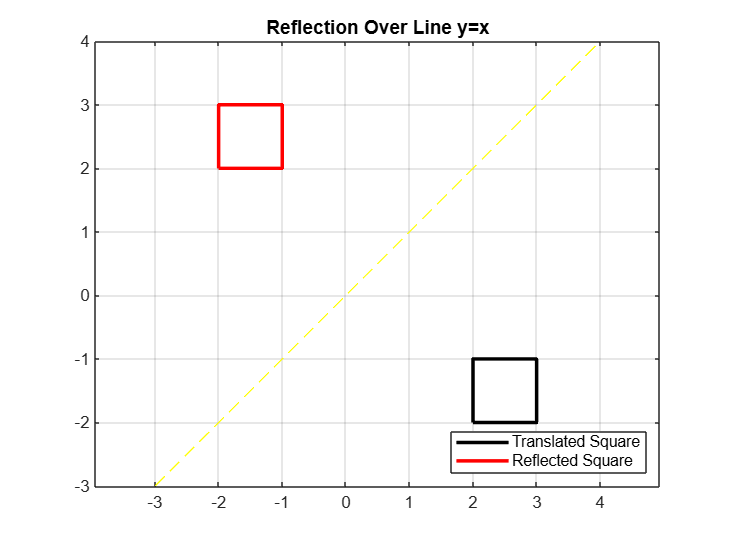

lab4_exercise5     % run the M-file for question 5

## Question 6

*For this exercise you are not supposed to include the picture, so you do not need to run the M-file*

type lab4_exercise6.m    %print the M-file for question 6


clf
S = [0,1,1,0,0;0,0,1,1,0;1,1,1,1,1]; 
M1 = [1,0,0.2;0,1,0;0,0,1]; % Horizontal translation for R
M2 = [1,0,0;0,1,0.2;0,0,1]; % Vertical translation fpr U
M3 = [1,0,-0.2;0,1,-0.2;0,0,1]; % Reverse: L + D

p = plot(S(1,:), S(2,:));
axis square, axis([-1,8,-1,8]), grid on;

% 30*R
for i = 1:30
    S = M1 * S;
    set(p, 'XData', S(1,:), 'YData', S(2,:));
    pause(0.1);
end

% 30*U
for i = 1:30
    S = M2 * S;
    set(p, 'XData', S(1,:), 'YData', S(2,:));
    pause(0.1);
end

% 30(L+D)
for i = 1:30
    S = M3 * S;
    set(p, 'XData', S(1,:), 'YData', S(2,:));
    pause(0.1);
end


## Question 7

*For this exercise you are not supposed to include the picture, so you do not need to run the M-file*

type lab4_exercise7.m    %print the M-file for question 7


clf
S = [0,1,1,0,0;0,0,1,1,0;1,1,1,1,1];

% 6*L
M1 = [1,0,-0.2;0,1,0;0,0,1];
p = plot(S(1,:), S(2,:));
axis equal, axis([-7,3,-8,2]), grid on;

for i = 1:30
    S = M1 * S; 
    set(p, 'XData', S(1,:), 'YData', S(2,:));
    pause(0.5);
end

% CCW with center at (1,0) 
theta = pi/10; 
Q = [cos(theta), -sin(theta), 0; 
     sin(theta),  cos(theta), 0; 
     0, 0, 1];

QP = [1,0,1; 0,1,0; 0,0,1] * Q * [1,0,-1; 0,1,0; 0,0,1];

for i = 1:5
    S = QP * S;
    set(p, 'XData', S(1,:), 'YData', S(2,:));
    pause(0.5);
end
